Note, the runtimes change a bit each time the script is run. But the relative comparisons stay similar.

clear
x = linspace(0,100,1e6);

No initialization for loop

tic
for i = 1:length(x)
    y(i) = x(i);
end
noInitFor = toc;

Initialization for loop

tic
y = zeros(1,numel(x));
for i = 1:length(x)
    y(i) = x(i);
end
initFor = toc;

For each-ish loop

tic
for value = x
    y = value;
end
eachIsh = toc;

Direct assignment

tic
y = x;
direct = toc;

Plot them up to compare

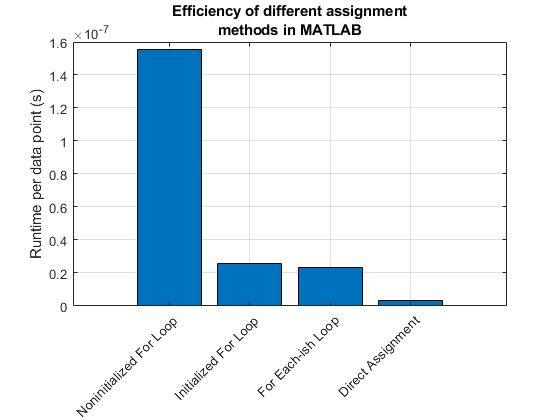

bar([noInitFor,initFor,eachIsh,direct]./length(x))
ylabel("Runtime per data point (s)")
title(["Efficiency of different assignment", "methods in MATLAB"])
grid on
h = gca;
h.XTickLabel = ["Noninitialized For Loop","Initialized For Loop","For Each-ish Loop","Direct Assignment"];
h.XTickLabelRotation = 45;